## Multiple Pendulum

The dynamics of a child sitting on a swing or a golfer swinging his golf club is pretty quite simple as it is like a physics problem of a single pendulum. How about we increase the number of pendulums to two or more? The result is that the behavior of the system becomes a lot more complex and studying the dynamics is very difficult. Furthermore, the motion of the pendulum actually becomes chaotic, the topic we are focused on.

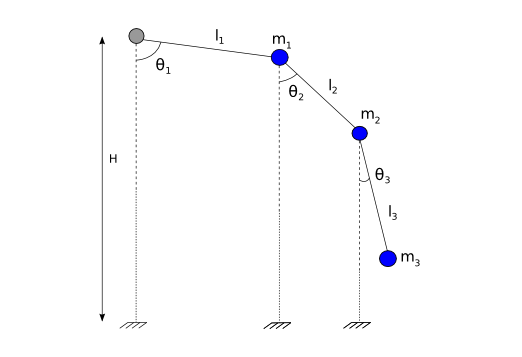

The dynamics of the system is very diffiicult to solve using plain Newton's laws of motion. Instead we use [Kane's Method](https://docs.sympy.org/dev/modules/physics/mechanics/kane.html) which describes the motion in 5 equations including: holonomic constraints, non-holonomic constraints, kinematic differential equations, dynamic equations, and differentiated non-holonomic equations. You can read more about it in the link. 

In this tutorial, the aim is to apply the techniques explained in" Neural Networks on Chaotic Systems" . A direct application of delay embeddings and ensemble kalman filtering does not work because we do not know the equations pertaining to the dynamics of the multiple pendulum. To aid us with this goal, code for pendulum dynamics using Kane's Method in Python was borrowed from [Gede et al. 2013](https://www.researchgate.net/publication/267490975_Constrained_Multibody_Dynamics_With_Python_From_Symbolic_Equation_Generation_to_Publication) and [VanderPlas J. 2017](https://jakevdp.github.io/blog/2017/03/08/triple-pendulum-chaos/). The code was changed a little to easily save the data into excel file so that the data can be used here in MATLAB. You can run python real_life filename x y  where filename will be the saved excel filename, x is the number of pendulums in the system, and y is the initial position in degrees.

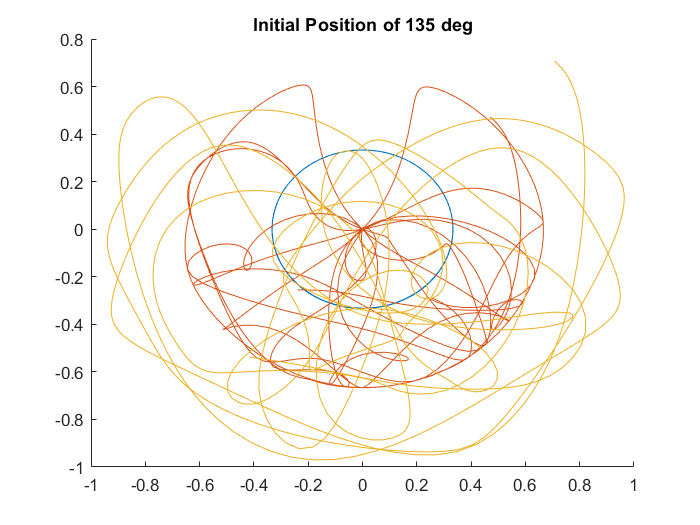

close all; clear all; clc;
%Training data using initial position of 135 degrees
[num3train, ~, ~] = xlsread("train3.xls");
figure(1);
hold on;
title("Initial Position of 135 deg");
plot(num3train(:, 1), num3train(:, 4));
plot(num3train(:, 2), num3train(:, 5));
plot(num3train(:, 3), num3train(:, 6));
hold off;

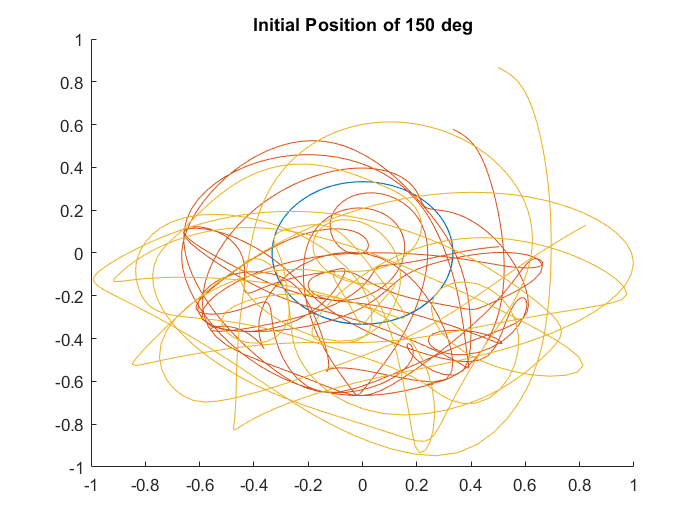

trainIn1 = num3train(1:end-1, [1 4]);
trainIn2 = num3train(1:end-1, [2 5]);
trainIn3 = num3train(1:end-1, [3 6]);
trainOut1 = num3train(2:end, [1 4]);
trainOut2 = num3train(2:end, [2 5]);
trainOut3 = num3train(2:end, [3 6]);
nn1 = NN(trainIn1, trainOut1);
nn2 = NN(trainIn2, trainOut2);
nn3 = NN(trainIn3, trainOut3);

%Testing data using initial position of 150 degrees
[num3test, ~, ~] = xlsread("test3.xls");
figure(2);
hold on;
title("Initial Position of 150 deg");
plot(num3test(:, 1), num3test(:, 4));
plot(num3test(:, 2), num3test(:, 5));
plot(num3test(:, 3), num3test(:, 6));
hold off;

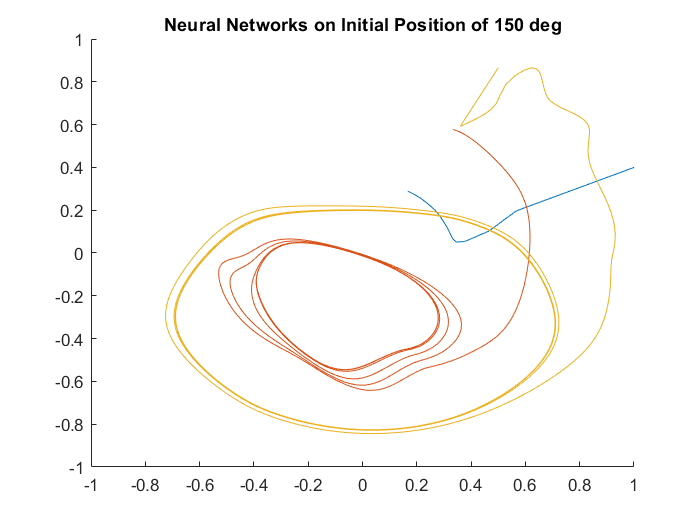

testingData(num3test, nn1, nn2, nn3);

The neural networks graph was not really able to model the dynamics of the trple pendulum. Hence better way to model the dynamics by improving the neural network structure or using other methods is recommended.

### Helper Functions

function [nn] = NN(in, out) 
nn = feedforwardnet([5 5 5 10]);
nn.layers{1}.transferFcn = 'elliotsig';
nn.layers{2}.transferFcn = 'logsig';
nn.layers{3}.transferFcn = 'tansig';
nn.layers{4}.transferFcn = 'purelin';
nn = train(nn,in.',out.');
end

function [] = testingData(data, nn1, nn2, nn3)
[time, ~] = size(data);
testTraj1(1,:)= [data(1, 1); data(1, 4)];
curr = [data(1, 1); data(1, 4)];
for i = 2 : time
    next = nn1(curr);
    testTraj1(i, :) = next.';
    curr = next;
end
testTraj2(1,:)= [data(1, 2); data(1, 5)];
curr = [data(1, 2); data(1, 5)];
for i = 2 : time
    next = nn2(curr);
    testTraj2(i, :) = next.';
    curr = next;
end
testTraj3(1,:)= [data(1, 3); data(1, 6)];
curr = [data(1, 2); data(1, 5)];
for i = 2 : time
    next = nn3(curr);
    testTraj3(i, :) = next.';
    curr = next;
end


figure(3);
hold on;
title("Neural Networks on Initial Position of 150 deg");
plot(testTraj1(:, 1), testTraj1(:, 2));
plot(testTraj2(:, 1), testTraj2(:, 2));
plot(testTraj3(:, 1), testTraj3(:, 2));
xlim([-1 1])
ylim([-1 1])
hold off;

end